**Задание 1**

**Вариант 1**

**Выполнил: Борисов Д.А.**

N_var1 = 9*10^6;
Fs_var1 = 4*10^6;
fpass_var1 = 667000;

clearvars all
close all

По расчетам с поомщью Filter Designer получены коэффиценты

Num = matfile('Num.mat').Num;

## Расчет на CPU

% Сформировать случайный сигнал как массив из N случайных значений
N = N_var1; % [Гц]
% Генерация отсчетов шума
noise = randn(1, N);
% Задать частоту дискретизации отсчетов случайного сигнала Fs
Fs = Fs_var1; % [Гц]
% Задать частоту среза фильтра fpass
fpass = fpass_var1; % [Гц]
% Фильтрация шума
filtered = filter(Num, 1, noise);
%% Построение графиков

% Вектор частот
tic; % начало подсчета времени.
f = (0:(N-1))*Fs/N;
time_CPU = toc; %конец подсчета времени

Вывод результатов

message = strcat('Время работы на CPU:', num2str(time_CPU), ' cекунд');
disp(message)

Время работы на CPU:0.11053 cекунд


## Построение графиков

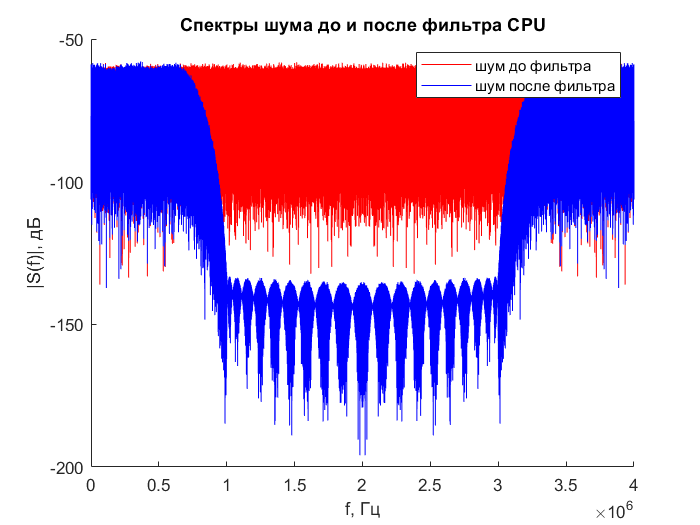

figure;
hold on;
plot (f, 20*log10(abs(fft(noise)/N)), 'r')
plot (f, 20*log10(abs(fft(filtered)/N)), 'b')
hold off;
title ('Спектры шума до и после фильтра CPU')
legend('шум до фильтра', 'шум после фильтра')
xlabel ('f, Гц')
ylabel ('|S(f)|, дБ')

## Расчет на GPU

Перенос данных на GPU


% Сформировать случайный сигнал как массив из N случайных значений
N = N_var1; % [Гц]

gN = gpuArray(N); % перевод на GPU

% Генерация отсчетов шума
noise = randn(1, N);
% Задать частоту дискретизации отсчетов случайного сигнала Fs
Fs = Fs_var1; % [Гц]
gFs = gpuArray(Fs); % перевод на GPU

% Задать частоту среза фильтра fpass
gfpass = gpuArray(fpass_var1); % [Гц]

% переведем коэффициенты на GPU
gNum = gpuArray(Num);

% переведем шум на GPU
gnoise = gpuArray(noise);

% Фильтрация шума
filtered = filter(gNum, 1, gnoise);

% Вектор частот
tic; % начало подсчета времени.
gf = (0:(N-1))*Fs/N; % расчет на GPU
time_GPU = toc; %конец подсчета времени 

% переход обратн она CPU
f = gather(gf)

f = 	1.0e+06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Вывод результатов

message = strcat('Время работы на GPU:', num2str(time_GPU), ' cекунд');
disp(message)

Время работы на GPU:0.03314 cекунд


## Построение графиков

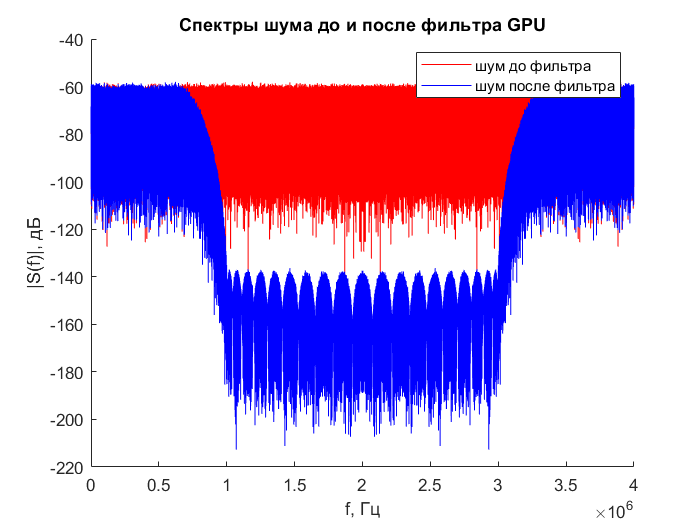

figure;
hold on;
plot (f, 20*log10(abs(fft(noise)/N)), 'r')
plot (f, 20*log10(abs(fft(filtered)/N)), 'b')
hold off;
title ('Спектры шума до и после фильтра GPU')
legend('шум до фильтра', 'шум после фильтра')
xlabel ('f, Гц')
ylabel ('|S(f)|, дБ')